# Homework 2.1

## Plot the distributions.

The solved Poisson process is

    P ( N(t_0 + 5) - N(t_0)=k ) = \frac{(5.5)^k e^{-5.5}}{k!}.

We have

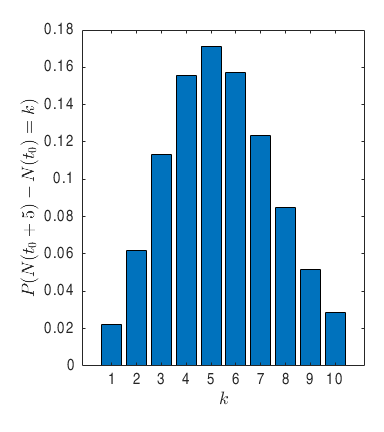

clearvars;
lambda = 1.1;
t = 5.0;
probfunc = @(k) exp(k.*log(lambda.*t) - lambda.*t - arrayfun(@(x) sum(log(cumsum(ones([x,1])))), k));
bar(probfunc(cumsum(ones([10,1]))));
xlabel('$k$', 'Interpreter', 'latex');
ylabel('$P( N(t_0 + 5) - N(t_0)=k )$', 'Interpreter', 'latex');
tight_layout([0.2, 0.4], 12);